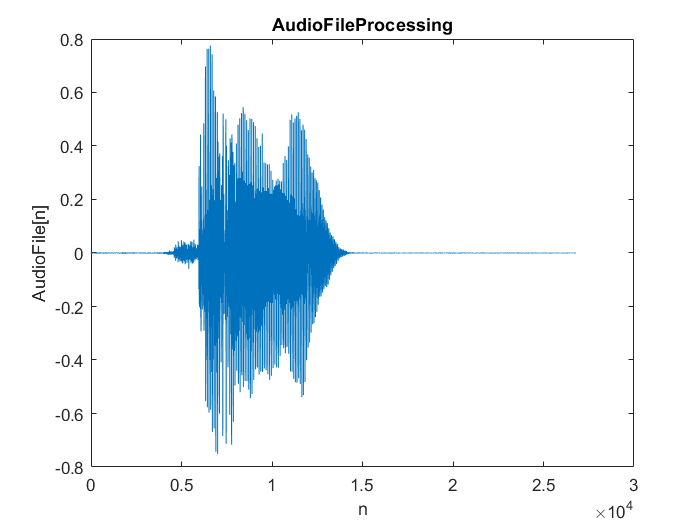

[audioData,fs] =  audioread('message.wav');
plot(audioData)
xlabel('n');
ylabel('AudioFile[n]');
title('AudioFileProcessing');

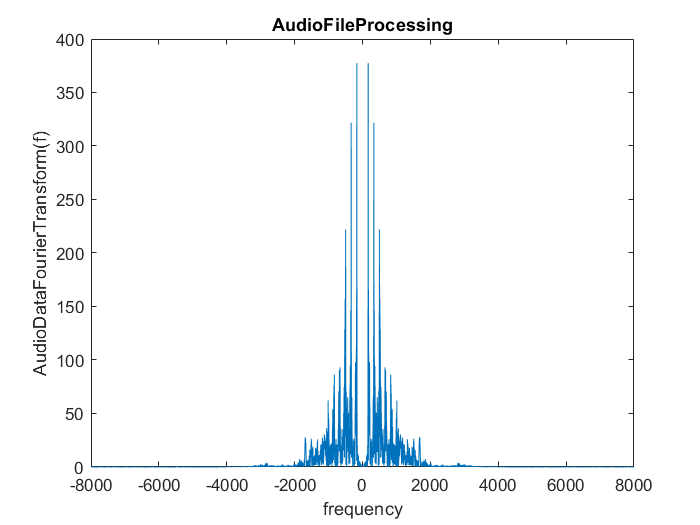

[audioDataSdf,audioDataFourierTransform] = sdf(transpose(audioData));
size(audioDataFourierTransform,2);
domain = linspace(-pi,pi,size(audioDataFourierTransform,2));
finalDomain = (domain/(2*pi))*fs;
finalDomain(1) - finalDomain(end);
figure
plot(finalDomain,abs(audioDataFourierTransform))
xlabel('frequency');
ylabel('AudioDataFourierTransform(f)');
title('AudioFileProcessing');

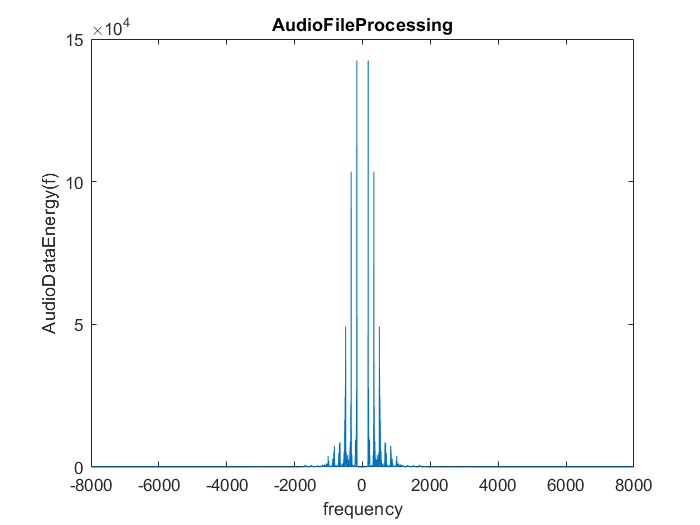

plot(finalDomain,abs(audioDataSdf))
xlabel('frequency');
ylabel('AudioDataEnergy(f)');
title('AudioFileProcessing');

powerAbs = abs(audioDataSdf);
totalEnergy = sum(powerAbs);
maxPower = max(powerAbs);
peakEnergy = find(powerAbs == maxPower);
centerFrequency = mean(peakEnergy);
power99 = totalEnergy*0.99;
freqIterator = 1000;% 1kHz
boundedEnergy = calEnergy(powerAbs,centerFrequency,freqIterator);
while boundedEnergy < power99
    freqIterator = freqIterator + 1;
    boundedEnergy = calEnergy(powerAbs,centerFrequency,freqIterator);
end
startBound = centerFrequency - freqIterator;
endBound = centerFrequency + freqIterator;
normalizedStartBound = finalDomain(startBound:endBound);
vpa(normalizedStartBound(end)) - vpa(normalizedStartBound(1))

$$ans = 3050.2930963670989967795321717858$$

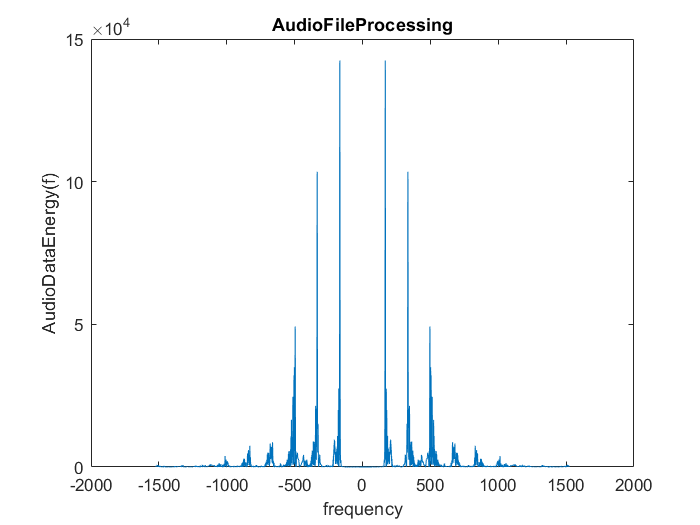

cutSignal = zeros(1,size(normalizedStartBound,2));
cutSignal(1:end) = powerAbs(startBound:endBound);
figure
plot(normalizedStartBound,cutSignal)
xlabel('frequency');
ylabel('AudioDataEnergy(f)');
title('AudioFileProcessing');

signalBound = 2*freqIterator

signalBound = 5106

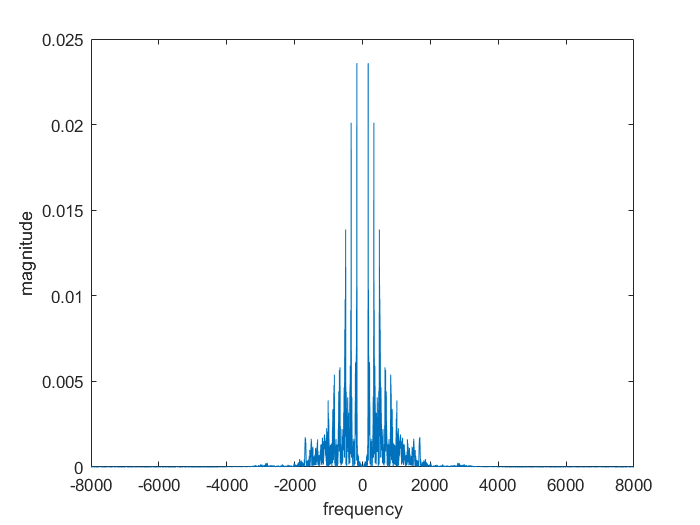

clc
[signal,fs] = audioread('message.wav');
[signalFourierTransform,frequency] = standardFourierTransform(signal,fs);
figure()
title('fourier transform of signal')
plot(frequency,abs(signalFourierTransform));
xlabel('frequency');
ylabel('magnitude');

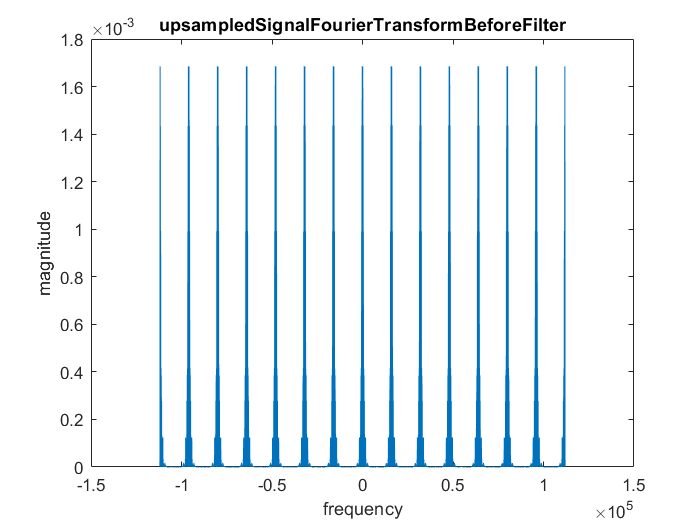

%% upsampleing 
upsamplingIntFactor = 14; % 204/16 = 12.75 -> signal should be upsampled at least by 13
% in order to avoid any disturbance ,it is being considered 14 instead.
upSampled = upsample(signal,upsamplingIntFactor);
fsNew = fs*upsamplingIntFactor;
[out,f] = standardFourierTransform(upSampled,fsNew);
figure();
plot(f,abs(out));
title('upsampledSignalFourierTransformBeforeFilter');
xlabel('frequency');
ylabel('magnitude');

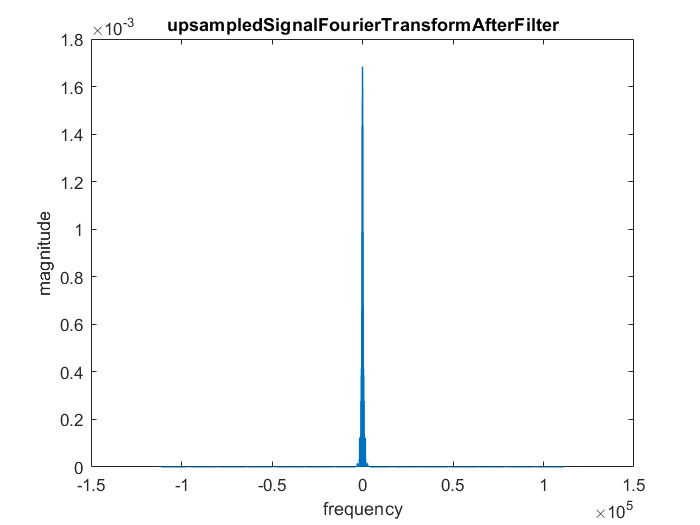

% loading designed filter
load('Hd.mat') 
% in order to remove aditional signals added because of upsamping we need
% to filter them.
upSampled = filter(Hd,upSampled);
[out,f] = standardFourierTransform(upSampled,fsNew);
figure();
plot(f,abs(out));
title('upsampledSignalFourierTransformAfterFilter');
xlabel('frequency');
ylabel('magnitude');

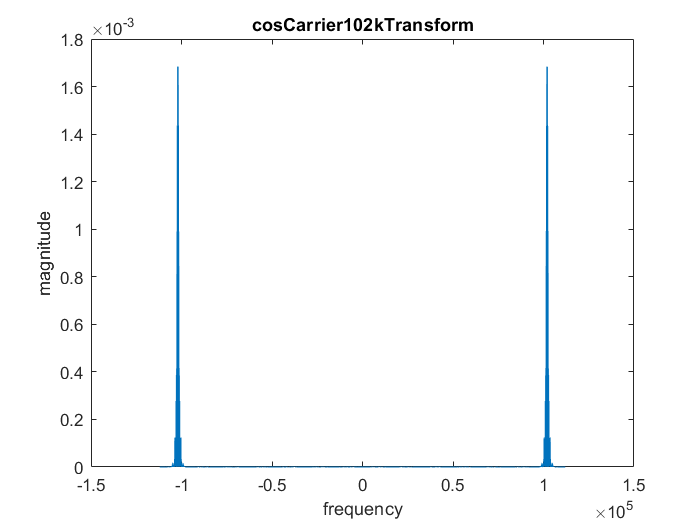

%% setting up carrier
t = (1:length(upSampled))/fsNew;
fc = 102000;
cosCarrier = cos(2*pi*fc*t);
%% multiplying
modulatedSignal = 2*cosCarrier.*transpose(upSampled);
[cosCarrierTransform,freq] = standardFourierTransform(modulatedSignal,fsNew);
figure();
plot(freq,abs(cosCarrierTransform));
title('cosCarrier102kTransform');
xlabel('frequency');
ylabel('magnitude');

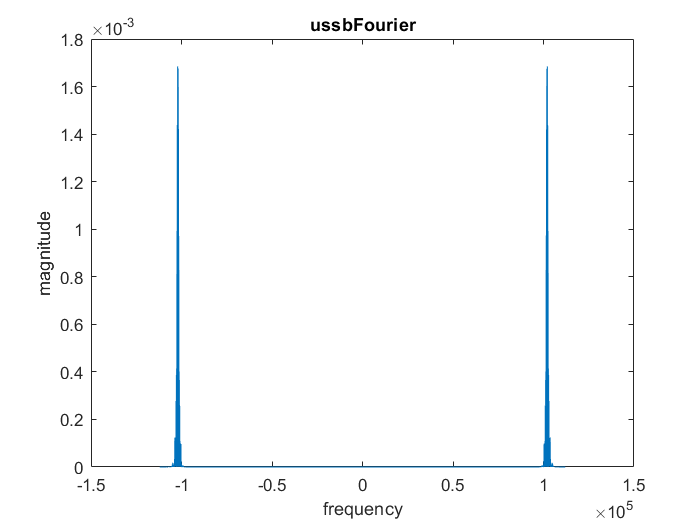

load('thirdHighPass102k.mat')
ussb = filter(thirdHighPass102k,modulatedSignal);
[ussbFourier,freq] = standardFourierTransform(ussb,fsNew);
figure();
plot(freq,abs(ussbFourier));
title('ussbFourier');
xlabel('frequency');
ylabel('magnitude');

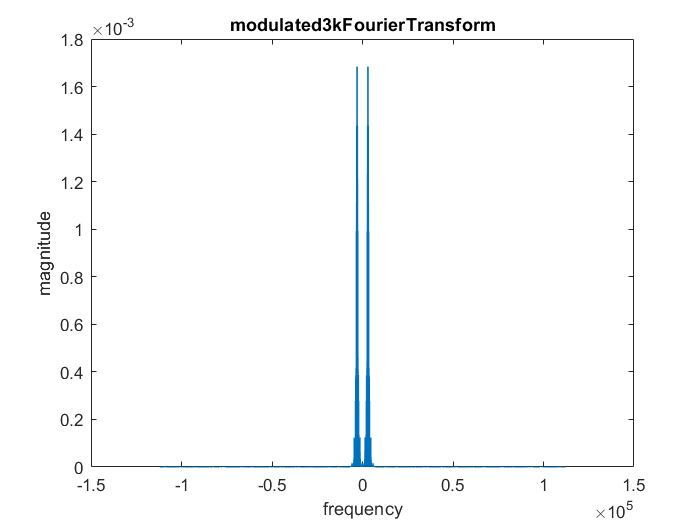

%% Question 2 with multiple multiplier
%% first carrier
%% fsNew=fs*upsamplingIntFactor;
t = (1:length(upSampled))/fsNew;
firstCosFrequency3k=3000;
firstCosCarrier3k = cos(2*pi*firstCosFrequency3k*t);
modulated3k = 2*firstCosCarrier3k.*transpose(upSampled);
[modulated3kFourierTransform,freq] = standardFourierTransform(modulated3k,fsNew);

figure()
plot(freq,abs(modulated3kFourierTransform));
title('modulated3kFourierTransform');
xlabel('frequency');
ylabel('magnitude');

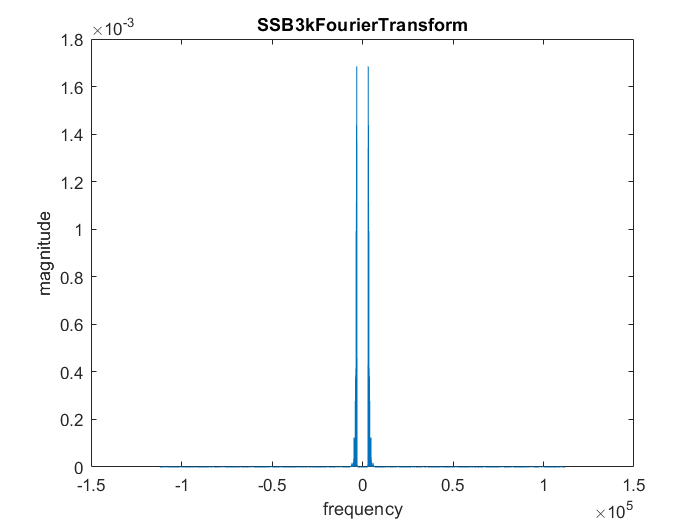

load('first3kHighPassFilter.mat')
firstModulatedSSB = filter(first3kHighPassFilter,modulated3k);
[SSB3kFourierTransform,freq] = standardFourierTransform(firstModulatedSSB,fsNew);
figure();
plot(freq,abs(SSB3kFourierTransform));
title('SSB3kFourierTransform');
xlabel('frequency');
ylabel('magnitude');

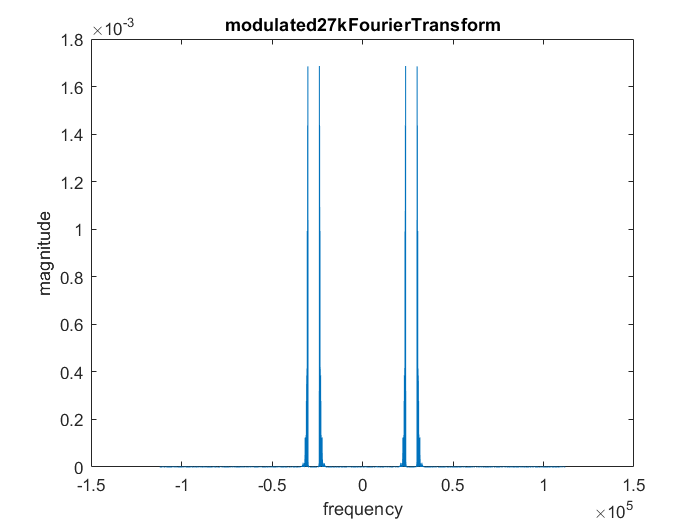

%% second carrier
secondCosFrequency27k=27000;
secondCosCarrier3k = cos(2*pi*secondCosFrequency27k*t);
modulated27k = 2*secondCosCarrier3k.*(firstModulatedSSB);
[modulated27kFourierTransform,freq] = standardFourierTransform(modulated27k,fsNew);
figure();
plot(freq,abs(modulated27kFourierTransform));
title('modulated27kFourierTransform');
xlabel('frequency');
ylabel('magnitude');

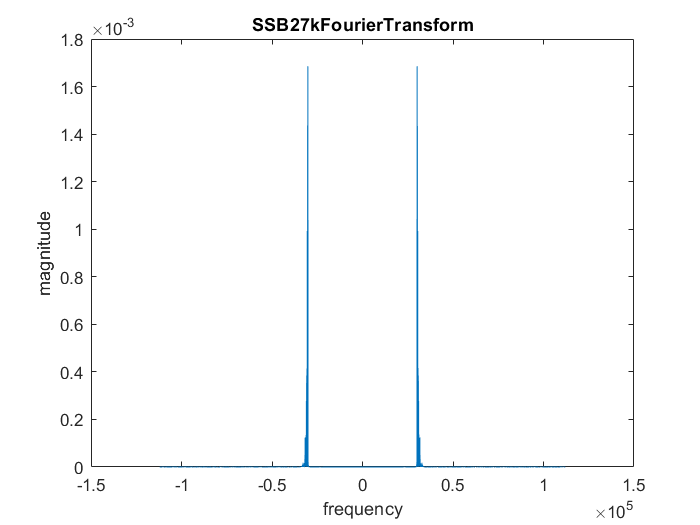

load('secondHighPass30k.mat')
secondModulatedSSB = filter(secondHighPass30k,modulated27k);
[SSB27kFourierTransform,freq] = standardFourierTransform(secondModulatedSSB,fsNew);
figure();
plot(freq,abs(SSB27kFourierTransform));
title('SSB27kFourierTransform');
xlabel('frequency');
ylabel('magnitude');

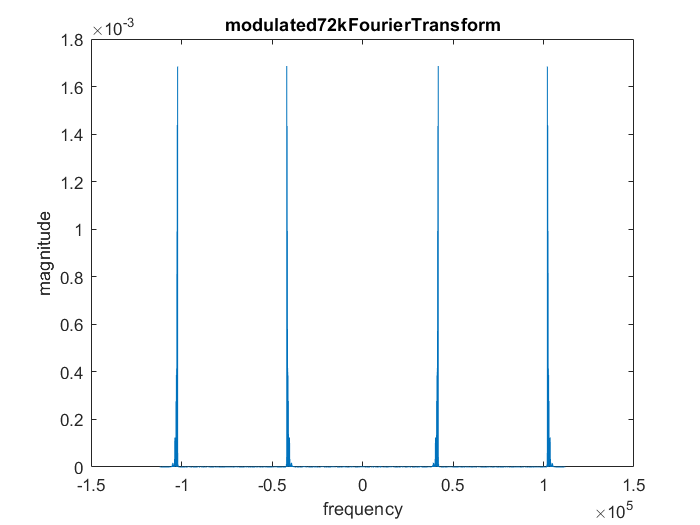

%% last carrier
thirdCosFrequency72k=72000;
thirdCosCarrier72k = cos(2*pi*thirdCosFrequency72k*t);
modulated72k = 2*thirdCosCarrier72k.*secondModulatedSSB;
[SSB72kFourierTransfrom,freq] = standardFourierTransform(modulated72k,fsNew);
figure();
plot(freq,abs(SSB72kFourierTransfrom));
title('modulated72kFourierTransform');
xlabel('frequency');
ylabel('magnitude');

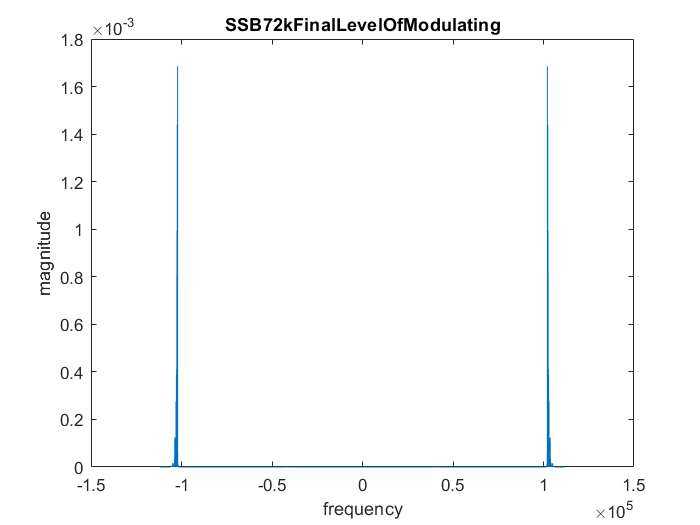

load('thirdHighPass102k.mat')
finalModulated = filter(thirdHighPass102k,modulated72k);
[finalModulatedFourierTransform,freq] = standardFourierTransform(finalModulated,fsNew);
figure();
plot(freq,abs(finalModulatedFourierTransform));
title('SSB72kFinalLevelOfModulating');
xlabel('frequency');
ylabel('magnitude');

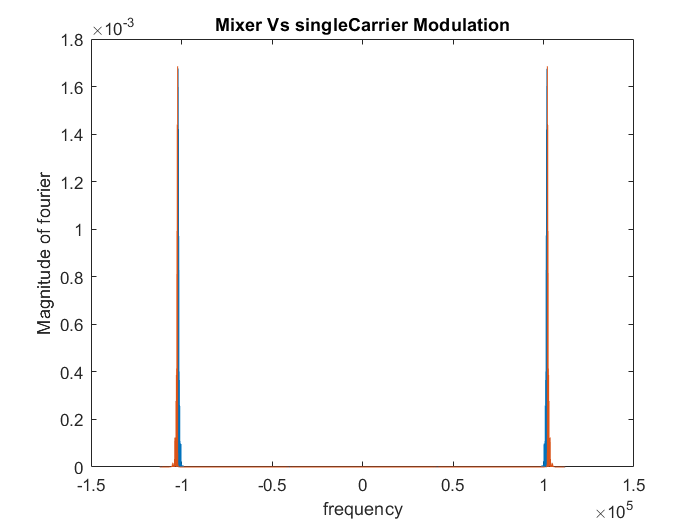

%% comparing the results
figure()
plot(freq,abs(ussbFourier));
hold on
plot(freq,abs(finalModulatedFourierTransform));
title('Mixer Vs singleCarrier Modulation');
ylabel('Magnitude of fourier');
xlabel('frequency');

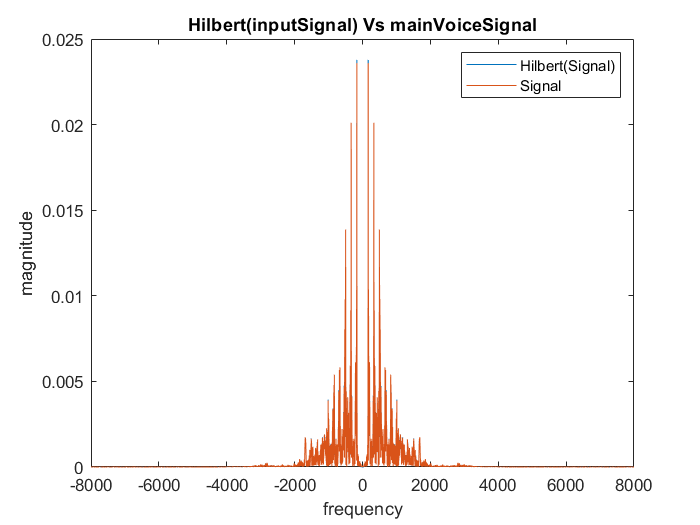

%% Question 2 setting up the hilbert window
load('Hilbert.mat')
[fft_signal,~] = standardFourierTransform(signal,fs);
hilbert_signal= filter(Hilbert,signal);
[fft_signal_hilbert,freq] = standardFourierTransform(hilbert_signal,fs);
figure()
title('Hilbert(inputSignal) Vs mainVoiceSignal');
plot(freq,abs(fft_signal_hilbert));

hold on
plot(freq,abs(fft_signal));
title('Hilbert(inputSignal) Vs mainVoiceSignal');
legend('Hilbert(Signal)','Signal')
xlabel('frequency');
ylabel('magnitude');

error = immse(abs(fft_signal),abs(fft_signal_hilbert))

error = 2.0448e-10

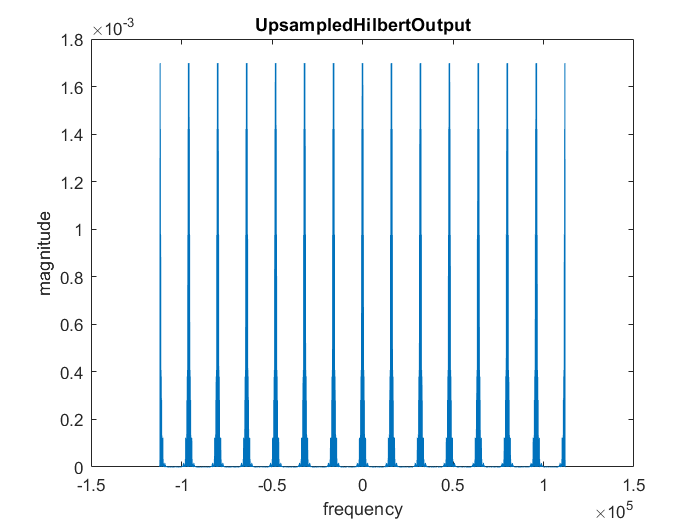

%% upsampeling hilbert transform of signal
upsamplingIntFactor = 14;
up_signal_hilbert = upsample(hilbert_signal,upsamplingIntFactor);
[out,f] = standardFourierTransform(up_signal_hilbert,fs*upsamplingIntFactor);
figure();
plot(f,abs(out));
title('UpsampledHilbertOutput');
xlabel('frequency');
ylabel('magnitude');

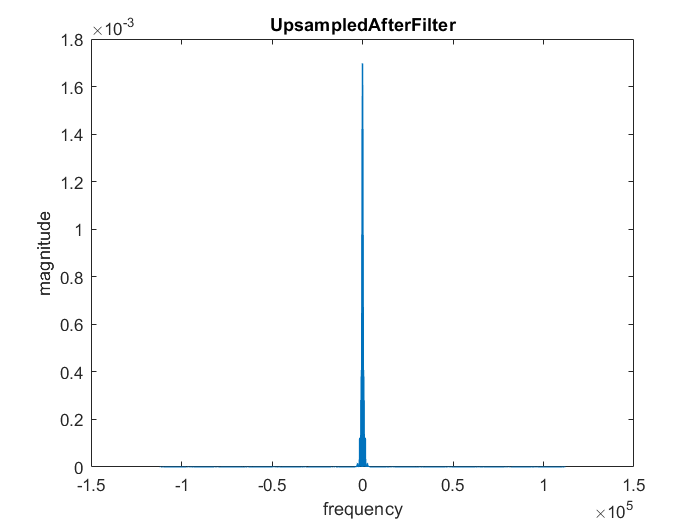

% loading designed filter
load('Hd.mat')
up_signal_hilbert = filter(Hd,up_signal_hilbert);
[out,f] = standardFourierTransform(up_signal_hilbert,fs*upsamplingIntFactor);
figure();
plot(f,abs(out));
title('UpsampledAfterFilter');
xlabel('frequency');
ylabel('magnitude');

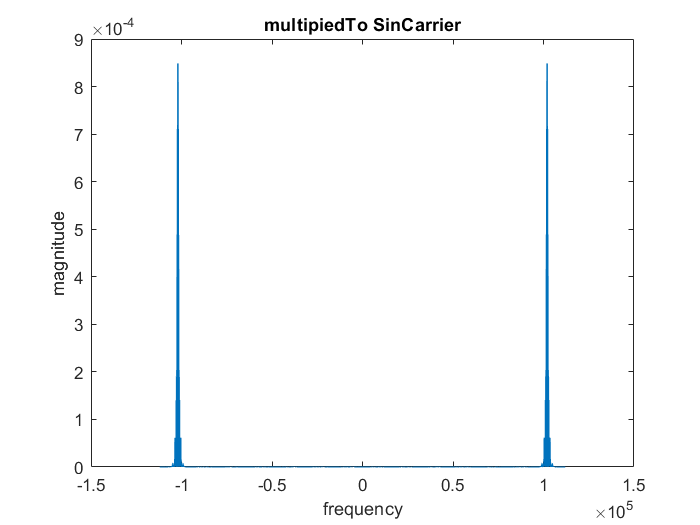

%% multipying to carrier
fsNew = fs*upsamplingIntFactor;
t = (1:length(upSampled))/fsNew;
fc = 102000;
sinCarrier = sin(2*pi*fc*t);
xHilSin = sinCarrier.*transpose(up_signal_hilbert);
[cosCarrierTransform,freq] = standardFourierTransform(xHilSin,fsNew);
figure();
plot(freq,abs(cosCarrierTransform));
title('multipiedTo SinCarrier');
xlabel('frequency');
ylabel('magnitude');

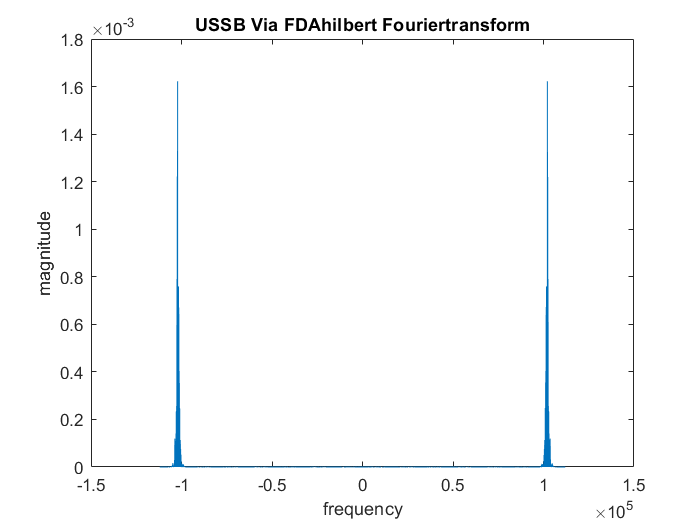

%%
final_signal = modulatedSignal./2-xHilSin;
[out_hil,f] = standardFourierTransform(final_signal,fsNew);
figure()
plot(f,abs(out_hil));
title('USSB Via FDAhilbert Fouriertransform');
ylabel('magnitude');
xlabel('frequency');

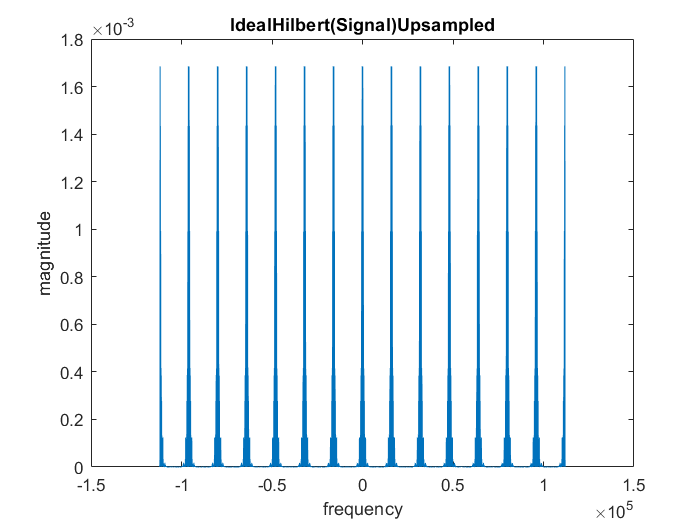

%% using another way to make hilbert transform
hilbert_signal = imag(hilbert(signal));
upsamplingIntFactor = 14;
up_signal_hilbert = upsample(hilbert_signal,upsamplingIntFactor);
[out,f] = standardFourierTransform(up_signal_hilbert,fs*14);
figure();
plot(f,abs(out));
title('IdealHilbert(Signal)Upsampled');
xlabel('frequency');
ylabel('magnitude');

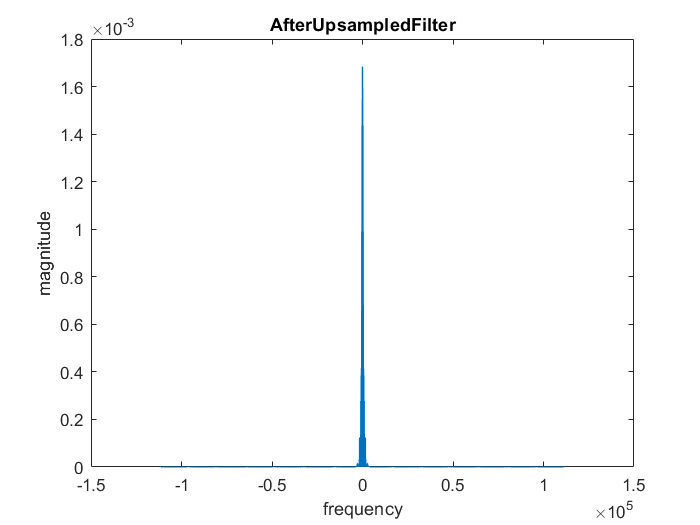

% loading designed filter
load('Hd.mat')
up_signal_hilbert = filter(Hd,up_signal_hilbert);
[out,f] = standardFourierTransform(up_signal_hilbert,fs*upsamplingIntFactor);
figure();
plot(f,abs(out));
title('AfterUpsampledFilter');
xlabel('frequency');
ylabel('magnitude');

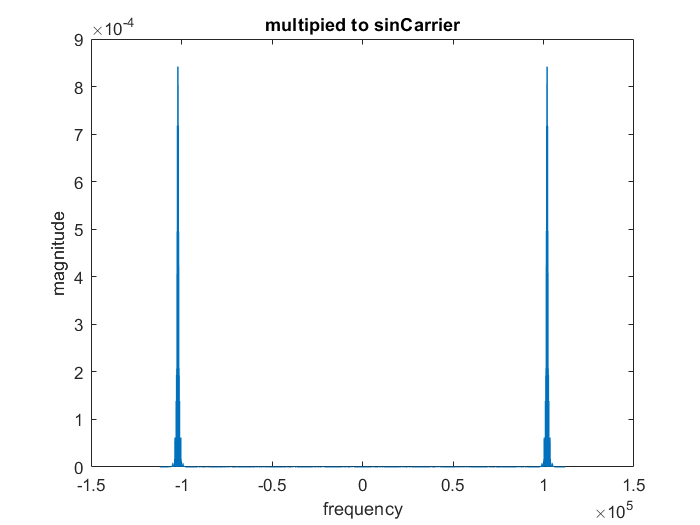

fs_new=fs*upsamplingIntFactor;
t = (1:length(upSampled))/fsNew;
fc = 102000;
sinCarrier = sin(2*pi*fc*t);
xHilSin = sinCarrier.*transpose(up_signal_hilbert);
[cosCarrierTransform,freq] = standardFourierTransform(xHilSin,fs_new);
figure();
plot(freq,abs(cosCarrierTransform));
title('multipied to sinCarrier');
xlabel('frequency');
ylabel('magnitude');

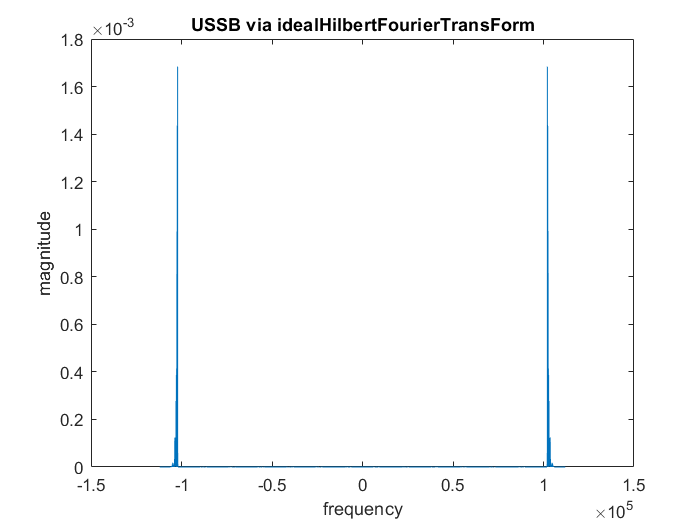

final_signal = modulatedSignal./2-xHilSin;
[out_ideal,f] = standardFourierTransform(final_signal,fs_new);
figure()
plot(f,abs(out_ideal));
title('USSB via idealHilbertFourierTransForm');
ylabel('magnitude');
xlabel('frequency');

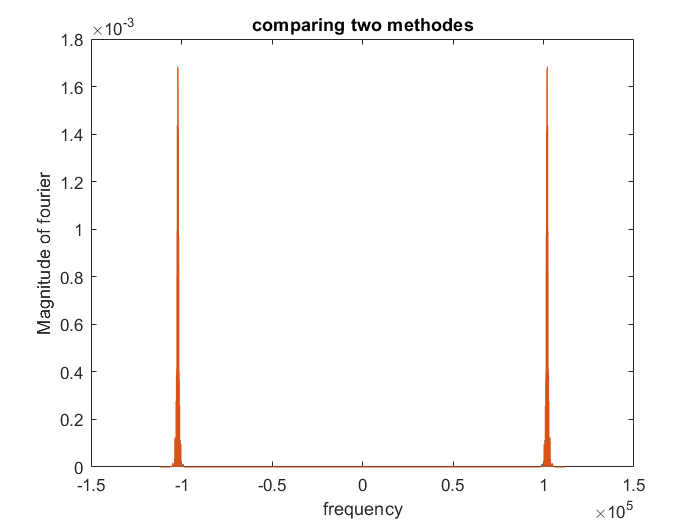

%% comparing the results of bad modelators
figure('name','comparing two methodes')

plot(freq,abs(out_hil));
hold on
plot(freq,abs(ussbFourier));

title('comparing two methodes');
ylabel('Magnitude of fourier');
xlabel('frequency');

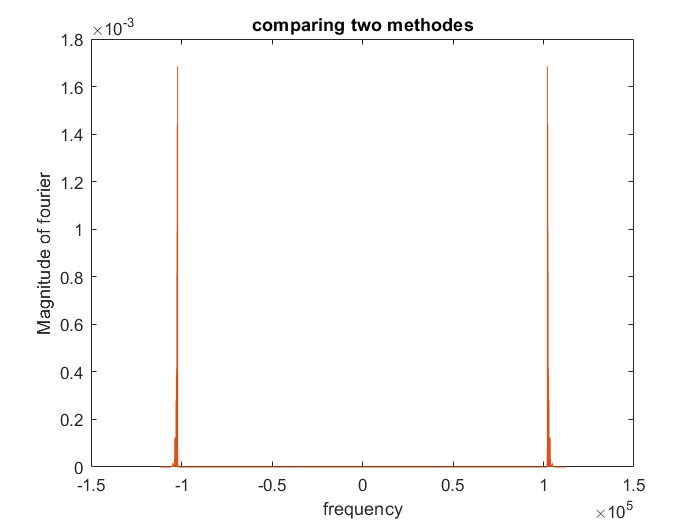

%% comparing the results of good modelators
figure('name','comparing two methodes')
gain=max(abs(finalModulatedFourierTransform))/max(abs(out_ideal));
plot(freq,gain*abs(out_ideal));
hold on
plot(freq,abs(finalModulatedFourierTransform));
title('comparing two methodes');
ylabel('Magnitude of fourier');
xlabel('frequency');

function [out,standardDomain] = standardFourierTransform(signal,fs)
n = length(signal);
fourier=fft(signal,n);
fourier = fourier/fs;
out = fftshift(fourier);
domain = linspace(-pi,pi,length(out));
standardDomain = domain*fs/(2*pi);
end

function [out,Tsignal] = sdf(signal)
Tsignal = fourierDiscreteStandardTransform(signal);
out = Tsignal.*conj(Tsignal);
end

function out = fourierDiscreteStandardTransform(signal)
out = fftshift(fft(signal,size(signal,2)));
end

function boundedEnergy = calEnergy(powerSignal,center,range)
boundedEnergy = sum(powerSignal(center-range:center+range));
end
